% Identify SHAPC Scenarios
clear;

setup;

dataset = 'cifar10';
config = dataset_configs.(dataset);
num_sessions = config.num_sessions;
num_classes = config.num_classes;
cls_per_task = config.cls_per_task;
samples_per_cls = config.samples_per_cls;
if isfield(config, 'init_cls')
    init_cls = config.init_cls;
else
    init_cls = cls_per_task; % If init_cls is undefined, assume init_cls = cls_per_task
end

subset_total = 50;

output_class_sheet = true; % Outputs a list of the classification for each image
                            % you can leave as false for now.

kruskal_wallis = true;

class_sheet_filename = "C:\Users\Akua\OneDrive - Rowan University\Masters\Research\SHAPC Scenarios.xlsx";

thresholds = zeros(1,length(algs));
all_BCs = zeros(subset_total,length(algs));
all_foms = zeros(subset_total*length(algs),4);

for i=1:subset_total

    scn_vals = zeros(length(algs), 4);

    for a=1:length(algs)
        alg = algs(a);
    
        % Initialize sample counters for each scenario
        s1_samples = 0;
        s2_samples = 0;
        s3_samples = 0;
        s4_samples = 0;
    
        % Load SHAPCs
        if i==1
            if strcmp(dataset, "cifar100")
                save_path = sprintf("%s/%s/shapc_vals_first_last_2000.mat", alg, dataset);
            elseif strcmp(dataset, "imagenet200")
                save_path = sprintf("%s/%s/shapc_vals_first_last_4000.mat", alg, dataset);
            else
                save_path = sprintf("%s/%s/shapc_vals_first_last_1000.mat", alg, dataset);
            end
        else
            if strcmp(alg, "dsal")
                alg = "ds-al";
            end
            save_path = sprintf("subset_testing/%s/%s_shapc_vals_subset_%d.mat", dataset, alg, i-1);
        end
    
        if ~isfile(save_path)
            disp("Could not find shapc file at'" + filename + "'.");
            continue
        end
        shapc_struct = load(save_path);


        % Load preds from txt file
        preds_struct = struct();
        
        if i==1
            filename = sprintf("preds/%s_preds.mat", dataset);
            if ~isfile(filename)
                error("Could not find preds file at'" + filename + "'.");
            end
        
            mat_data = load(filename);
            if isfield(mat_data.preds_data, alg)
                preds_struct = mat_data.preds_data.(alg);
            end
        else
            filename = sprintf("subset_testing/%s/%s_%s_shap_preds_subset_%d.out", dataset, alg, dataset, i-1);
        end
        
        if ~isfile(filename)
            disp("Could not find preds file at'" + filename + "'.");
            continue
        end
    
        lines = readlines(filename);
        
        for j=1:length(lines)
            line = lines(j);
            if ~contains(line, "Sample")
                continue
            end
            parts = split(line, ':');
            tokens = regexp(parts{1}, '\d+', 'match');
            sample = tokens{1};
    
            prediction = regexp(parts{2}, '\d+', 'match');
            pred1 = str2double(prediction{1});
            pred2 = str2double(prediction{2});
        
            %fprintf('Sample: %s\n', sample);
            %fprintf("Pred 1: %d\n",pred1);
            %fprintf("Pred 2: %d\n",pred2);
        
            sm_str = sprintf("sample%s", sample);
        
            true_label = floorDiv(str2double(sample),100);
            task = floorDiv(true_label, cls_per_task);
            pred_str = sprintf("pred_ses%d", task);
        
            preds_struct.(sm_str).(pred_str) = pred1;
            preds_struct.(sm_str).pred_ses4 = pred2;
        end

        threshold = getshapcthreshold(alg, dataset, a, i-1);
        thresholds(i) = threshold;

        if strcmp(dataset, 'cifar100') || strcmp(dataset, 'imagenet200')
            pred2_ses = 'pred_ses9';
        else
            pred2_ses = 'pred_ses4';
        end
        

        iters = samples_per_cls*(num_classes-cls_per_task);
        alg_classifications = zeros(iters, 1);

        for j=1:iters
            sample_str = ['sample', num2str(j - 1)];
    
            cls = floor((j-1) / samples_per_cls);
            if cls < init_cls
                task = 0;
            else
                task = floor((cls-init_cls) / cls_per_task) + 1;
            end

            pred_str = ['pred_ses', num2str(task)];
    
            pred1 = preds_struct.(sample_str).(pred_str);
            pred2 = preds_struct.(sample_str).(pred2_ses);
            
            classification = classify_scenario(string(j-1), pred1, pred2, threshold, dataset, shapc_struct);
            alg_classifications(j) = classification;
            
            switch classification
                case 1
                    s1_samples = s1_samples + 1;
                case 2
                    s2_samples = s2_samples + 1;
                case 3
                    s3_samples = s3_samples + 1;
                case 4
                    s4_samples = s4_samples + 1;
            end
        %print(line)
        end


        % Generate Percentages
        total_samples = s1_samples + s2_samples + s3_samples + s4_samples;
        %fprintf("Total Samples: %d\n", total_samples)
        
        s1_percentage = (s1_samples / total_samples) * 100;
        s2_percentage = (s2_samples / total_samples) * 100;
        s3_percentage = (s3_samples / total_samples) * 100;
        s4_percentage = (s4_samples / total_samples) * 100;

        % Show in Chart
        percentages = [s1_percentage, s2_percentage, s3_percentage, s4_percentage];

        % Add to Table
        scn_vals(a,:) = percentages;
        %fprintf("Finished %s, Subset %d.\n", algs(a), i);
    end

    % Generate Figures of Merit
    foms = zeros(length(algs), 4);

    % Figure of Merit 1
    foms(:,1) = scn_vals(:,4);
    
    % Figure of Merit 2
    first_scn = 1;
    second_scn = 4;
    foms(:,2) = scn_vals(:, second_scn) - scn_vals(:, first_scn);
    
    % Figure of Merit 3
    first_scn = 2;
    second_scn = 4;
    foms(:,3) = scn_vals(:, second_scn) + scn_vals(:, first_scn);
    
    % Figure of Merit 4
    first_scn = 2;
    second_scn = 3;
    foms(:,4) = scn_vals(:, second_scn) + scn_vals(:, first_scn);

    all_foms((i-1)*length(algs)+1:i*length(algs),:) = foms;

    % Perform Borda Count

    % Rank FoMs 1-3 ascending
    [~,p] = sort(foms,'ascend');
    [~, r] = sort(p);

    % Rank FoMs 4 descending
    [~,p] = sort(foms,'descend');
    [~, r(:,4)] = sort(p(:,4));

    % Sum Rankings
    BC = sum(r,2);
    
    all_BCs(i,:) = BC;
    %{
    if output_class_sheet
        %write_cell = ['B' char(string(i+6))];
        write_cell = ['D' char(string(i+6))];
        writematrix(BC', class_sheet_filename, 'Sheet', "Subset Testing", 'Range', write_cell);
    end
    %}
    fprintf("Finished Subset %d.\n", i);
end

Finished Subset 1.
Finished Subset 2.
Finished Subset 3.
Finished Subset 4.
Finished Subset 5.
Finished Subset 6.
Finished Subset 7.
Finished Subset 8.
Finished Subset 9.
Finished Subset 10.
Finished Subset 11.
Finished Subset 12.
Finished Subset 13.
Finished Subset 14.
Finished Subset 15.
Finished Subset 16.
Finished Subset 17.
Finished Subset 18.
Finished Subset 19.
Finished Subset 20.
Finished Subset 21.
Finished Subset 22.
Finished Subset 23.
Finished Subset 24.
Finished Subset 25.
Finished Subset 26.
Finished Subset 27.
Finished Subset 28.
Finished Subset 29.
Finished Subset 30.
Finished Subset 31.
Finished Subset 32.
Finished Subset 33.
Finished Subset 34.
Finished Subset 35.
Finished Subset 36.
Finished Subset 37.
Finished Subset 38.
Finished Subset 39.
Finished Subset 40.
Finished Subset 41.
Finished Subset 42.
Finished Subset 43.
Finished Subset 44.
Finished Subset 45.
Finished Subset 46.
Finished Subset 47.
Finished Subset 48.
Finished Subset 49.
Finished Subset 50.


if output_class_sheet
    %write_cell = ['B' char(string(i+6))];
    write_cell = 'B7';
    writematrix(all_BCs, class_sheet_filename, 'Sheet', "Subset Testing", 'Range', write_cell);
end

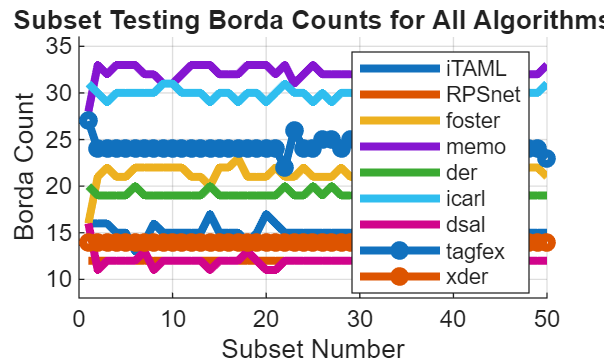

% Plot BCs
if exist('all_BCs', 'var') && any(all_BCs, 'all')
    clf
    set(gca, 'LineStyleOrder', {'-', '-o'});
    hold on
    plot(all_BCs, 'LineWidth', 3, 'MarkerSize', 4)
    legend(algs)
    title('Subset Testing Borda Counts for All Algorithms');
    xlabel('Subset Number');
    ylabel('Borda Count');
    axis([0 50 8 36])
    grid on;
    %hold off
    %6,8
end

if kruskal_wallis
    %write_cell = ['B' char(string(i+6))];
    write_cell = 'Q7';
    writematrix(all_foms, class_sheet_filename, 'Sheet', "Subset Testing", 'Range', write_cell);
end

% Confidence Intervals
% Load data from sheet
all_BCs = readmatrix(class_sheet_filename,"Sheet","Subset Testing","Range",'B7:J56');

all_BCs =     16    12    16    28    20    31    16    27    14
    16    12    21    33    19    30    11    24    14
    16    12    22    32    19    29    12    24    14
    15    12    21    33    19    30    12    24    14
    15    12    21    33    19    30    12    24    14
    13    12    22    33    20    30    12    24    14
    14    12    22    32    19    30    13    24    14
    16    12    22    32    19    30    11    24    14
    15    12    22    31    19    31    12    24    14
    15    12    22    31    19    31    12    24    14
    15    12    22    32    19    30    12    24    14
    15    12    21    33    19    30    12    24    14
    15    12    21    33    19    30    12    24    14
    17    12    20    33    20    29    11    24    14
    15    12    22    32    19    30    12    24    14



means = [];
CIs = [];
figure;
hold on

for k=1:length(algs)
    class1 = all_BCs(:,k);
    
    % Calculate 95% confidence intervals for classes 1 and 2
    % Find standard errors
    x = class1;
    m_class1 = mean(x);
    SEM_class1 = std(x)/sqrt(length(x));                             
    
    % Establish z-score for 95% confidence interval
    zs = 1.96;                                  
    
    % Calculate 95% confidence intervals
    CI_class1 = [m_class1 - zs*SEM_class1, m_class1 + zs*SEM_class1];    
    
    % Print confidence intervals
    fprintf('%s 95%% CI: [%.3f, %.3f]\n', algs(k), CI_class1(1), CI_class1(2));
    
    % Define the means and confidence intervals
    means = [means, mean(class1)];
    CIs = [CIs; CI_class1];
    
    % Plotting confidence intervals as boxes (Figure 2)
    
    
    % Colors for each model
    colors = {'k', 'k'};  
    
    % Plot the boxes for confidence intervals
    rectangle('Position', [k-0.25, CIs(k,1), 0.5, CIs(k,2) - CIs(k,1)], 'EdgeColor', colors{1}, 'LineWidth', 2);
    
    % Add mean markers
    plot(k, means(k), 's', 'MarkerEdgeColor', colors{1}, 'MarkerFaceColor', colors{1});

end

iTAML 95% CI: [14.971, 15.349]
RPSnet 95% CI: [12.000, 12.000]
foster 95% CI: [21.131, 21.669]
memo 95% CI: [31.848, 32.392]
der 95% CI: [19.057, 19.263]
icarl 95% CI: [29.927, 30.393]
dsal 95% CI: [11.751, 12.169]
tagfex 95% CI: [23.823, 24.257]
xder 95% CI: [14.000, 14.000]


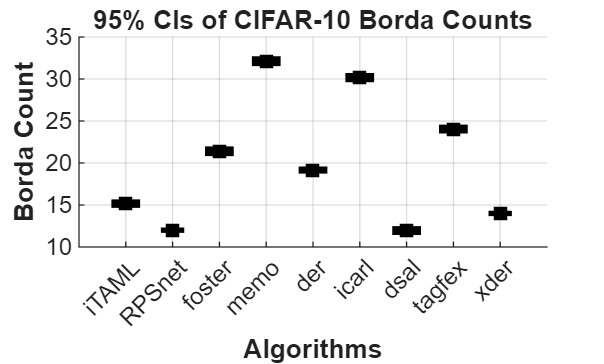

% Customize the plot
set(gca, 'XTick', 1:length(algs), 'XTickLabel', algs);
xlabel('Algorithms', 'FontWeight', 'bold');
ylabel('Borda Count', 'FontWeight', 'bold');
title('95% CIs of CIFAR-10 Borda Counts');

% Add grid lines for clarity
grid on;

hold off;

% Kruskal Wallis Ranking
kruskalwallis(all_BCs)